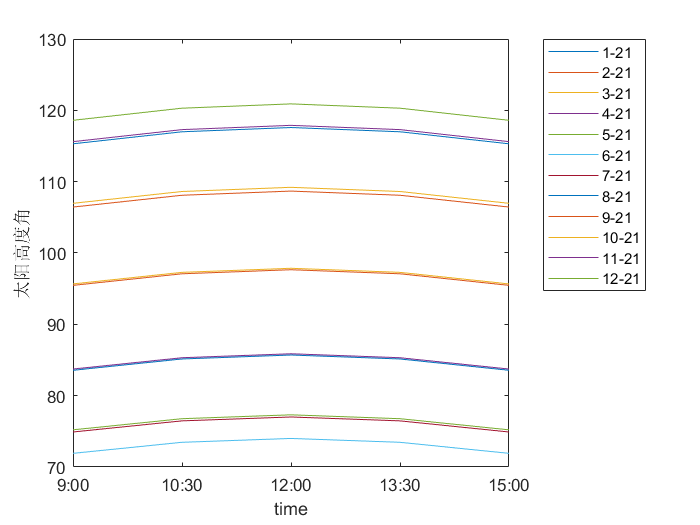

clc;clear
tic
data = readmatrix("附件.xlsx");
time = [9,10.5,12,13.5,15];
date = {'2023-1-21','2023-2-21','2023-3-21','2023-4-21','2023-5-21','2023-6-21','2023-7-21','2023-8-21','2023-9-21','2023-10-21','2023-11-21','2023-12-21'};
date2 = {'1-21','2-21','3-21','4-21','5-21','6-21','7-21','8-21','9-21','10-21','11-21','12-21'};
for m = 1:length(date)
    date1 = date{m};
    jindu = 95.4;
    weidu = 39.4;
    % 太阳时角
    w = pi*(time-12)/12;
    % 太阳赤纬角
    % 定义每个月的天数
    dateNum = datenum(date1, 'yyyy-mm-dd');
    yer = year(date1);
    firstDayNum = datenum(sprintf('%d-01-01', yer), 'yyyy-mm-dd');
    D = dateNum - firstDayNum + 1;
    delta = 23.45*sin(2*pi*(284+D)/365)*(pi/180);
    % 太阳高度角
    aphls = (pi/2 - asin(cos(delta)*cos(weidu)*cos(w)+sin(delta)*sin(weidu))).*180/pi;
    plot(time,aphls)
    hold on 
    xticks([9,10.5,12,13.5,15]);
    xticklabels({'9:00','10:30','12:00','13:30','15:00'});
    ylabel('太阳高度角')
    xlabel('time');
    legend(date2,'Location','bestoutside')
end
saveas(gcf,'太阳高度角.png','png')

    % 太阳方位角
    gamas = acos((sin(delta).*cos(weidu)-cos(delta).*cos(w).*sin(weidu))./(cos(aphls)))-pi;
